# Track-to-Track Fusion for Automotive Safety Applications

This example shows how to fuse tracks from two vehicles in order to provide a more comprehensive estimate of the environment that can be seen by each vehicle. The example demonstrates the use of a track-level fuser and the object track data format. In this example, you use the driving scenario and models from Automated Driving Toolbox™ and the tracking and track fusion models from Sensor Fusion and Tracking Toolbox™.

## Motivation

Automotive safety applications rely on the fusion of data from different sensor systems mounted on the vehicle. Individual vehicles fuse sensor detections by using either a centralized tracker or by taking a more decentralized approach and fusing tracks produced by individual sensors. In addition to intravehicle data fusion, the fusion of data from multiple vehicles provides added benefits, which include better coverage, situational awareness, and safety. [1] This intervehicle sensor fusion approach takes advantage of the variety of sensors and provides better coverage to each vehicle, because it uses data updated by sensors on other vehicles in the area. Governments and vehicle manufacturers have long recognized the need to share information between vehicles in order to increase automotive safety. For example, the Dedicated Short-Range Communications (DSRC) Service was established to provide a communications service for intervehicle information sharing. [2]

While sensor fusion across multiple vehicles is beneficial, most vehicles are required to meet certain safety requirements even if only internal sensors are available. Therefore, the vehicle is likely to be equipped with a tracker and/or a track fuser that provide situational awareness at the single vehicle level. As a result, the assumption made in this example is that vehicles share situational awareness by broadcasting tracks and performing track-to-track fusion. 

This example demonstrates the benefit of fusing tracks from two vehicles to enhance situational awareness and safety. Note that this example does not simulate the communications systems. Instead, the example assumes that a communications system provides the bandwidth required to transmit tracks between the two vehicles. 

## Track-to-Track Architecture

The following block diagram depicts the main functions in the two vehicles. 

Vehicle 1 has two sensors, each providing detections to a local tracker. The tracker uses the detections from the local sensors to track objects and outputs these local tracks to the vehicle track fuser. Vehicle 2 has a single sensor, which feeds detections to the local tracker on vehicle 2. The local tracks from vehicle 2 are the input to the local track fuser on vehicle 2. 

The track fuser on each vehicle fuses the local vehicle tracks with the tracks received from the other vehicle's track fuser. After each update, the track fuser on each vehicle broadcasts its fused tracks, which feed into the next update of the track fuser on the other vehicle. 

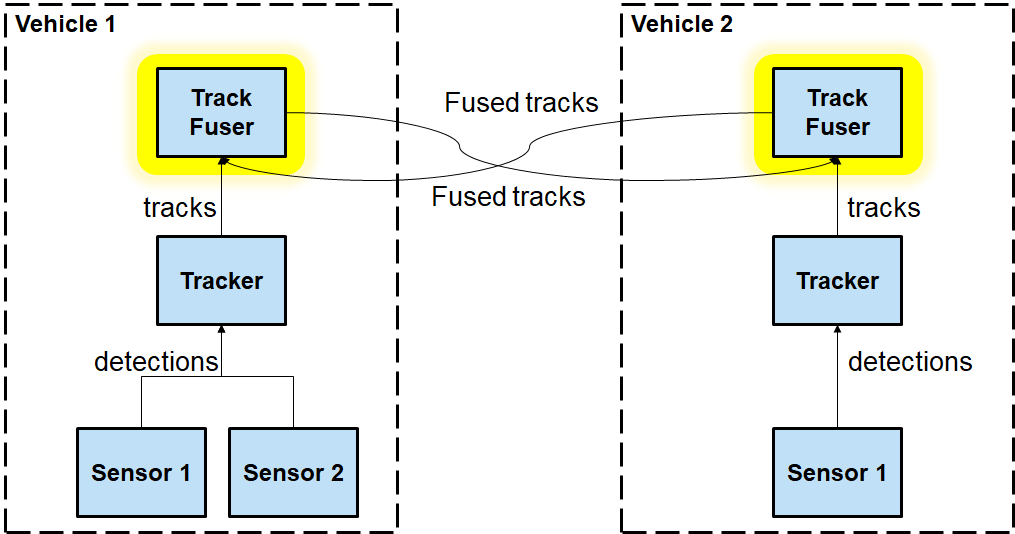

In this example, you use a [trackerJPDA](docid:fusion_ref#sysobj_tracker_jpda) object to define each vehicle tracker. 

% Create trackers for each vehicle
v1Tracker = trackerJPDA('TrackerIndex',1, 'DeletionThreshold', [4 4]); % Vehicle 1 tracker
v2Tracker = trackerJPDA('TrackerIndex',2, 'DeletionThreshold', [4 4]); % Vehicle 2 tracker
posSelector = [1 0 0 0 0 0; 0 0 1 0 0 0];

Note that in this architecture, the fused tracks from one vehicle are used to update the fused tracks on the other vehicle. These fused tracks are then broadcast back to the first vehicle. To avoid rumor propagation, be careful how tracks from another vehicle are used to update the track fuser. 

Consider the following rumor propagation example: at some update step, vehicle 1 tracks an object using its internal sensors. Vehicle 1 then fuses the object track and transmits it to vehicle 2, which now fuses the track with its own tracks and becomes aware of the object. Up to this point, this is exactly the goal of track-to-track fusion: to enhance the situational awareness of vehicle 2 with information from vehicle 1. Since vehicle 2 now knows about the object, it starts broadcasting the track as well, perhaps for the benefit of another vehicle (not shown in the example). 

However, vehicle 1 now receives track information from vehicle 2 about the object that only vehicle 1 actually tracks. So, the track fuser on vehicle 1 has to be aware that the tracks it gets from vehicle 2 about this object do not actually contain any new information updated by an independent source. To make the distinction between tracks that contain new information and tracks that just repeat information, you must define vehicle 2 as an *external source* to the track fuser on vehicle 1. Similarly, vehicle 1 must be defined as an external source to the track fuser on vehicle 2. Furthermore, you need to define only tracks that are updated by a track fuser based on information from an internal source as *self-reported*. By doing so, the track fuser in each vehicle is able to ignore updates from tracks that bounce back and forth between the track fusers without any new information in them. 

The local tracker of each vehicle tracks objects relative to the vehicle reference frame, called the ego frame. The track-to-track fusion is done at the scenario frame, which is the global level frame. The helper `egoToScenario` function transforms tracks from ego frame to the scenario frame. Similarly, the function `scenarioToEgo` transforms tracks from scenario frame to any of the ego frames. Both transformations rely on the `StateParameters` property of the [objectTrack](docid:fusion_ref#class_object_track) objects. Note that when the `trackFuser` object calculates the distance of a central track (in the scenario frame) to a local track (in any frame), it uses the `StateParameters` of the local track to perform the coordinate transformation.

To achieve the above `trackFuser` definitions, define the following sources as a [fuserSourceConfiguration](docid:fusion_ref#class_fuser_source_configuration) object.

% Define sources for each vehicle
v1TrackerConfiguration = fuserSourceConfiguration('SourceIndex',1,'IsInternalSource',true, ...   % v1Tracker is internal to v1Fuser
    "CentralToLocalTransformFcn", @scenarioToEgo, 'LocalToCentralTransformFcn', @egoToScenario); % Coordinate transformation
v2FuserConfiguration = fuserSourceConfiguration('SourceIndex',4,'IsInternalSource',false);       % v2Fuser is external to v2Fuser
v1Sources = {v1TrackerConfiguration; v2FuserConfiguration};
v2TrackerConfiguration = fuserSourceConfiguration('SourceIndex',2,'IsInternalSource',true, ...   % v2Tracker is internal to v2Fuser
    "CentralToLocalTransformFcn", @scenarioToEgo, 'LocalToCentralTransformFcn', @egoToScenario); % Coordinate transformation
v1FuserConfiguration = fuserSourceConfiguration('SourceIndex',3,'IsInternalSource',false);       % v1Fuser is external to v2Fuser
v2Sources = {v2TrackerConfiguration; v1FuserConfiguration};

You can now define each vehicle track fuser as a [trackFuser](docid:fusion_ref#sysobj_track_fuser) object.

stateParams = struct('Frame','Rectangular','Position',[0 0 0],'Velocity',[0 0 0]);
v1Fuser = trackFuser('FuserIndex',3,...
    'MaxNumSources',2,'SourceConfigurations',v1Sources,...
    'StateFusion','Intersection','DeletionThreshold',[3 3],...
    'StateParameters',stateParams);
v2Fuser = trackFuser('FuserIndex',4,...
    'MaxNumSources',2,'SourceConfigurations',v2Sources,'StateFusion',...
    'Intersection','DeletionThreshold',[3 3],...
    'StateParameters',stateParams);

% Initialize the following variables
fusedTracks1 = objectTrack.empty(0,1);
fusedTracks2 = objectTrack.empty(0,1);
wasFuser1Updated = false;
wasFuser2Updated = false;

## Scenario Definition

The following scenario shows two vehicles driving down a street. Vehicle 1 is in the lead, equipped with two forward-looking sensors: a short-range radar and a vision sensor. Vehicle 2, driving 10 meters behind vehicle 1, is equipped with a long-range radar. The right side of the street contains parked vehicles. A pedestrian stands between the vehicles. This pedestrian is shown as a dot at about X = 60 meters. 

Due to the short distance between vehicle 2 and vehicle 1, most of the vehicle 2 radar sensor coverage is occluded by vehicle 1. As a result, most of the tracks that the track fuser on vehicle 2 maintains are first initialized by tracks broadcast from vehicle 1.

% Create the drivingScenario object and the two vehicles
[scenario, vehicle1, vehicle2] = createDrivingScenario;

% Create all the sensors
[sensors, numSensors, attachedVehicle] = createSensors(scenario);

% Create display
[f,plotters] = createT2TDisplay(scenario, sensors, attachedVehicle);

The following chase plot is seen from the point of view of the second vehicle. An arrow indicates the position of the pedestrian that is almost entirely occluded by the parked vehicles and the first vehicle.

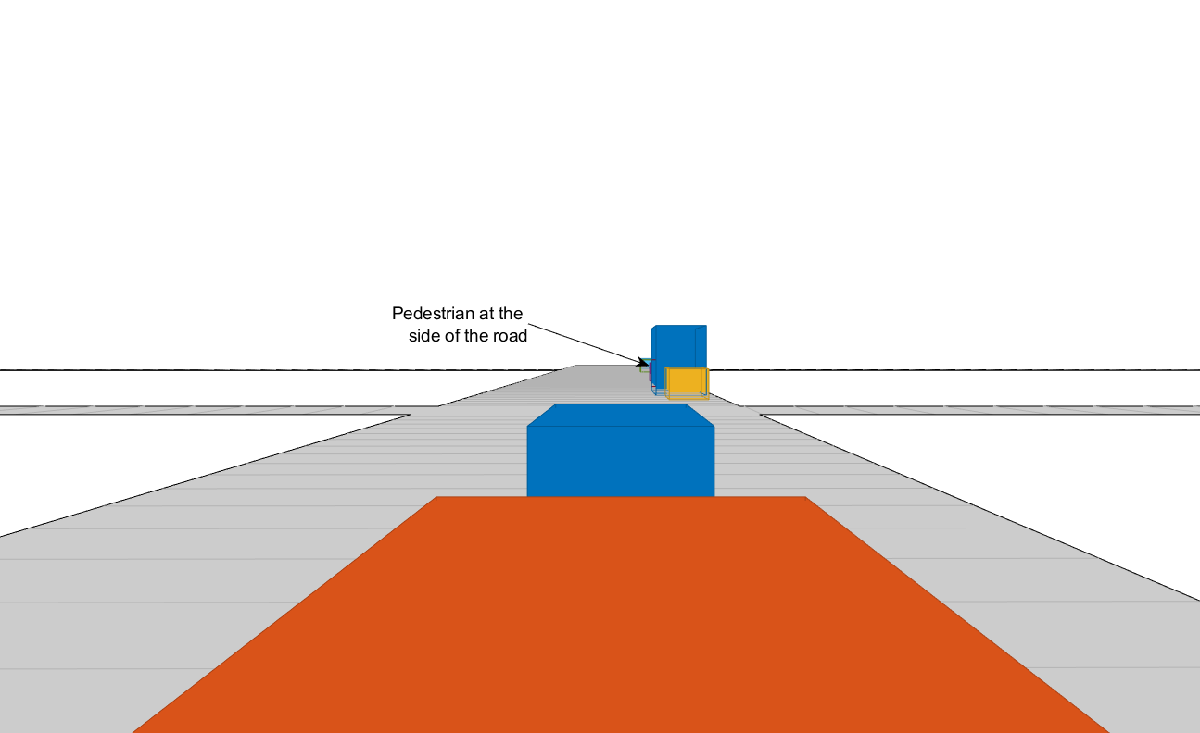

% Define each vehicle as a vehicle, sensors, a tracker, and plotters
v1 = struct('Actor', {vehicle1}, 'Sensors', {sensors(attachedVehicle==1)}, 'Tracker', {v1Tracker}, 'DetPlotter', {plotters.veh1DetPlotter}, 'TrkPlotter', {plotters.veh1TrkPlotter});
v2 = struct('Actor', {vehicle2}, 'Sensors', {sensors(attachedVehicle==2)}, 'Tracker', {v2Tracker}, 'DetPlotter', {plotters.veh2DetPlotter}, 'TrkPlotter', {plotters.veh2TrkPlotter});

## Simulation and Results

The following code runs the simulation.

running = true;

% For repeatable results, set the random number seed
s = rng;
rng(2019)
snaptimes = [0.5, 2.6, 4.4, 6.3, inf];
snaps = cell(numel(snaptimes,1));
i = 1;
f.Visible = 'on';
while running && ishghandle(f)
    time  = scenario.SimulationTime;
    
    % Detect and track at the vehicle level
    [tracks1,wasTracker1Updated] = detectAndTrack(v1,time,posSelector);
    [tracks2,wasTracker2Updated] = detectAndTrack(v2,time,posSelector);
    
    % Keep the tracks from the previous fuser update
    oldFusedTracks1 = fusedTracks1;
    oldFusedTracks2 = fusedTracks2;
    
    % Update the fusers
    if wasTracker1Updated || wasFuser2Updated
        tracksToFuse1 = [tracks1;oldFusedTracks2];
        if isLocked(v1Fuser) || ~isempty(tracksToFuse1)
            [fusedTracks1,~,~,info1] = v1Fuser(tracksToFuse1,time);
            wasFuser1Updated = true;
            pos = getTrackPositions(fusedTracks1,posSelector);
            plotTrack(plotters.veh1FusePlotter,pos);
        else
            wasFuser1Updated = false;
            fusedTracks1 = objectTrack.empty(0,1);
        end
    else
        wasFuser1Updated = false;
        fusedTracks1 = objectTrack.empty(0,1);
    end
    if wasTracker2Updated || wasFuser1Updated
        tracksToFuse2 = [tracks2;oldFusedTracks1];
        if isLocked(v2Fuser) || ~isempty(tracksToFuse2)
            [fusedTracks2,~,~,info2] = v2Fuser(tracksToFuse2,time);
            wasFuser2Updated = true;
            pos = getTrackPositions(fusedTracks2,posSelector);
            ids = string([fusedTracks2.TrackID]');
            plotTrack(plotters.veh2FusePlotter,pos,ids);
        else
            wasFuser2Updated = false;
            fusedTracks2 = objectTrack.empty(0,1);
        end
    else
        wasFuser2Updated = false;
        fusedTracks2 = objectTrack.empty(0,1);
    end
    
    % Update the display
    updateT2TDisplay(plotters, scenario, sensors, attachedVehicle)
    
    % Advance the scenario one time step and exit the loop if the scenario is complete
    running = advance(scenario);
    
    % Snap a shot at required times
    if time >= snaptimes(i)
        snaps{i} = getframe(f);
        i = i + 1;
    end
end

The figure shows the scene and tracking results at the end of the scenario.

### Tracking at the Beginning of the Simulation

When the simulation begins, vehicle 1 detects the vehicles parked on the right side of the street, then the tracks associated with the parked vehicles are confirmed. At this time, the only object detected and tracked by vehicle 2 tracker is vehicle 1 immediately in front of it. Once the vehicle 1 track fuser confirms the tracks, it broadcasts them, and the vehicle 2 track fuser fuses them. As a result, vehicle 2 becomes aware of the parked vehicles before it can detect them on its own.

showsnap(snaps, 1)

### Tracking the Pedestrian at the Side of the Street

As the simulation continues, vehicle 2 is able to detect and track the vehicles parked at the side as well, and fuses them with the tracks coming from vehicle 1. Vehicle 2 is able to detect and track the pedestrian about 4 seconds into the simulation, and vehicle 2 fuses the track associated with the pedestrian around 4.4 seconds into the simulation (see snapshot 2). However, it takes vehicle 2 about two seconds before it can detect and track the pedestrian by its own sensors (see snapshot 3). These two seconds could make a huge impact on the safety of the pedestrian if that pedestrian started crossing the street. 

showsnap(snaps, 2)
showsnap(snaps, 3)

### Avoiding Rumor Propagation

Finally, note how as the vehicles pass the objects, and these objects go out of their field of view, the fused tracks associated with these objects are dropped by both trackers (see snapshot 4). Dropping the tracks demonstrates that the fused tracks broadcast back and forth between the two vehicles are not used to propagate rumors. 

showsnap(snaps, 4)

% Restart the driving scenario to return the actors to their initial positions.
restart(scenario);

% Release all the sensor objects so they can be used again.
for sensorIndex = 1:numSensors
    release(sensors{sensorIndex});
end

% Return the random seed to its previous value
rng(s)

## Summary

In this example, you saw how track-to-track fusion can enhance the situational awareness and increase the safety in automotive applications. You saw how to set up a `trackFuser` to perform track-to-track fusion and how to define sources as either internal or external by using the `fuserSourceConfiguration` object. By doing so, you avoid rumor propagation and keep only the fused tracks that are really observed by each vehicle to be maintained.

## References

[1] Bharanidhar Duraisamy, Tilo Schwartz, and Christian Wohler, "Track level fusion algorithms for automotive safety applications", 2013 International Conference on Signal Processing, Image Processing & Pattern Recognition, IEEE, 2013.

[2] Federal Communications Commission, "Dedicated Short Range Communications Service", [https://www.fcc.gov/wireless/bureau-divisions/mobility-division/dedicated-short-range-communications-dsrc-service.](https://www.fcc.gov/wireless/bureau-divisions/mobility-division/dedicated-short-range-communications-dsrc-service)

## Supporting Functions

### createDrivingScenario

function [scenario, egoVehicle, secondVehicle] = createDrivingScenario
% createDrivingScenario Returns the drivingScenario defined in the Designer

% Construct a drivingScenario object.
scenario = drivingScenario('SampleTime', 0.05);

% Add all road segments
roadCenters = [50.8 0.5 0; 253.4 1.5 0];
roadWidth = 12;
road(scenario, roadCenters, roadWidth);

roadCenters = [100.7 -100.6 0; 100.7 103.7 0];
road(scenario, roadCenters);

roadCenters = [201.1 -99.2 0; 199.7 99.5 0];
road(scenario, roadCenters);

% Add the ego vehicle
egoVehicle = vehicle(scenario, 'ClassID', 1, 'Position', [65.1 -0.9 0]);
waypoints = [71 -0.5 0; 148.7 -0.5 0];
speed = 12;
trajectory(egoVehicle, waypoints, speed);

% Add the second vehicle
secondVehicle = vehicle(scenario, 'ClassID', 1, 'Position', [55.1 -0.9 0]);
waypoints = [61 -0.5 0; 138.7 -0.5 0];
speed = 12;
trajectory(secondVehicle, waypoints, speed);

% Add the parked cars
vehicle(scenario, 'ClassID', 1, 'Position', [111.0 -3.6 0]);
vehicle(scenario, 'ClassID', 1, 'Position', [140.6 -3.6 0]);
vehicle(scenario, 'ClassID', 1, 'Position', [182.6 -3.6 0]);
vehicle(scenario, 'ClassID', 1, 'Position', [211.3 -4.1 0]);

% Add pedestrian
actor(scenario, 'ClassID', 4, 'Length', 0.5, 'Width', 0.5, ...
    'Height', 1.7, 'Position', [130.3 -2.7 0], 'RCSPattern', [-8 -8;-8 -8]);

% Add parked truck
vehicle(scenario, 'ClassID', 2, 'Length', 8.2, 'Width', 2.5, ...
    'Height', 3.5, 'Position', [117.5 -3.5 0]);
end

### createSensors

function [sensors, numSensors, attachedVehicle] = createSensors(scenario)
% createSensors Returns all sensor objects to generate detections
% Units used in createSensors and createDrivingScenario
% Distance/Position - meters
% Speed             - meters/second
% Angles            - degrees
% RCS Pattern       - dBsm

% Assign into each sensor the physical and radar profiles for all actors
profiles = actorProfiles(scenario);
sensors{1} = radarDetectionGenerator('SensorIndex', 1, ...
    'SensorLocation', [3.7 0], 'MaxRange', 50, 'FieldOfView', [60 5], ...
    'ActorProfiles', profiles, 'HasOcclusion', true, 'HasFalseAlarms', false);
sensors{2} = visionDetectionGenerator('SensorIndex', 2, ...
    'MaxRange', 100, 'SensorLocation', [1.9 0], 'DetectorOutput', 'Objects only', ...
    'ActorProfiles', profiles);
sensors{3} = radarDetectionGenerator('SensorIndex', 3, ...
    'SensorLocation', [3.7 0], 'MaxRange', 120, 'FieldOfView', [30 5], ...
    'ActorProfiles', profiles, 'HasOcclusion', true, 'HasFalseAlarms', false);
attachedVehicle = [1;1;2];
numSensors = numel(sensors);
end

### scenarioToEgo

function trackInEgo = scenarioToEgo(trackInScenario)
% Performs coordinate transformation from scenario to ego coordinates
% trackInScenario has StateParameters defined to transform it from scenario
% coordinates to ego coordinates
% We assume a constant velocity model with state [x;vx;y;vy;z;vz]
egoPosInScenario = trackInScenario.StateParameters.Position;
egoVelInScenario = trackInScenario.StateParameters.Velocity;
stateInScenario = trackInScenario.State;
stateShift = [egoPosInScenario(1);egoVelInScenario(1);egoPosInScenario(2);egoVelInScenario(2);egoPosInScenario(3);egoVelInScenario(3)];
stateInEgo = stateInScenario - stateShift;
trackInEgo = objectTrack('UpdateTime',trackInScenario.UpdateTime,'State',stateInEgo,'StateCovariance',trackInScenario.StateCovariance,'StateParameters',trackInScenario.StateParameters);
end

### egoToScenario

function trackInScenario = egoToScenario(trackInEgo)
% Performs coordinate transformation from ego to scenario coordinates
% trackInEgo has StateParameters defined to transform it from ego
% coordinates to scenario coordinates
% We assume a constant velocity model with state [x;vx;y;vy;z;vz]
egoPosInScenario = trackInEgo.StateParameters.Position;
egoVelInScenario = trackInEgo.StateParameters.Velocity;
stateInScenario = trackInEgo.State;
stateShift = [egoPosInScenario(1);egoVelInScenario(1);egoPosInScenario(2);egoVelInScenario(2);egoPosInScenario(3);egoVelInScenario(3)];
stateInEgo = stateInScenario + stateShift;
trackInScenario = objectTrack('UpdateTime',trackInEgo.UpdateTime,'State',stateInEgo,'StateCovariance',trackInEgo.StateCovariance,'StateParameters',trackInEgo.StateParameters);
end

### detectAndTrack

function [tracks,wasTrackerUpdated] = detectAndTrack(agent,time,posSelector)
% Create detections from the vehicle
poses = targetPoses(agent.Actor);
[detections,isValid] = vehicleDetections(agent.Actor.Position,agent.Sensors,poses,time,agent.DetPlotter);

% Update tracks for the vehicle
if isValid
    agent.Tracker.StateParameters = struct(...
        'Frame','Rectangular', ...
        'Position', agent.Actor.Position, ...
        'Velocity', agent.Actor.Velocity);
    tracks = agent.Tracker(detections,time);
    tracksInScenario = tracks;
    for i = 1:numel(tracks)
        tracksInScenario(i) = egoToScenario(tracks(i));
    end
    pos = getTrackPositions(tracksInScenario,posSelector);
    plotTrack(agent.TrkPlotter,pos)
    wasTrackerUpdated = true;
else
    tracks = objectTrack.empty(0,1);
    wasTrackerUpdated = false;
end
end

function [objectDetections,isValid] = vehicleDetections(position, sensors, poses, time, plotter)
% Provides the detections for each vehicle. 

numSensors = numel(sensors);
objectDetections = {};
isValidTime      = false(1, numSensors);

% Generate detections for each sensor
for sensorIndex = 1:numSensors
    sensor = sensors{sensorIndex};
    [objectDets, ~, isValidTime(sensorIndex)] = sensor(poses, time);
    objectDets = cellfun(@(d) setAtt(d), objectDets, 'UniformOutput', false);
    
    if isa(sensors{sensorIndex},'radarDetectionGenerator')
        objectDets = helperClusterDetections(objectDets, 5);
    end
    numObjects = numel(objectDets);
    objectDetections = [objectDetections; objectDets(1:numObjects)]; %#ok<AGROW>
end
isValid = any(isValidTime);

% Plot detections
if numel(objectDetections)>0
    detPos = cellfun(@(d)d.Measurement(1:2), objectDetections, 'UniformOutput', false);
    detPos = cell2mat(detPos')' + position(1:2);
    plotDetection(plotter, detPos);
end
end

function d = setAtt(d)
% Set the attributes to be struct
d.ObjectAttributes = struct;
end

function detectionClusters = helperClusterDetections(detections, vehicleSize)
% helperClusterDetections  Helper to cluster detections in the example
N = numel(detections);
distances = zeros(N);
for i = 1:N
    for j = i+1:N
        if detections{i}.SensorIndex == detections{j}.SensorIndex
            distances(i,j) = norm(detections{i}.Measurement(1:2) - detections{j}.Measurement(1:2));
        else
            distances(i,j) = inf;
        end
    end
end
leftToCheck = 1:N;
i = 0;
detectionClusters = cell(N,1);
while ~isempty(leftToCheck)    
    % Remove the detections that are in the same cluster as the one under
    % consideration
    underConsideration = leftToCheck(1);
    clusterInds = (distances(underConsideration, leftToCheck) < vehicleSize);
    detInds = leftToCheck(clusterInds);
    clusterDets = [detections{detInds}];
    clusterMeas = [clusterDets.Measurement];
    meas = mean(clusterMeas, 2);
    i = i + 1;
    detectionClusters{i} = detections{detInds(1)};
    detectionClusters{i}.Measurement = meas;
    leftToCheck(clusterInds) = [];    
end
detectionClusters(i+1:end) = [];

% Since the detections are now for clusters, modify the noise to represent
% that they are of the whole car
for i = 1:numel(detectionClusters)
    measNoise = eye(6);
    measNoise(1:2,1:2) = vehicleSize^2 * eye(2);
    measNoise(4:5,4:5) = eye(2) * vehicleSize^2;
    detectionClusters{i}.MeasurementNoise = measNoise;
end
end

*Copyright 2019 The MathWorks, Inc.*